clf;
clear;

sea_house = imread("../images/sea_house.jpg");
[M,N,dim] = size(sea_house)

M = 460

N = 840

dim = 3

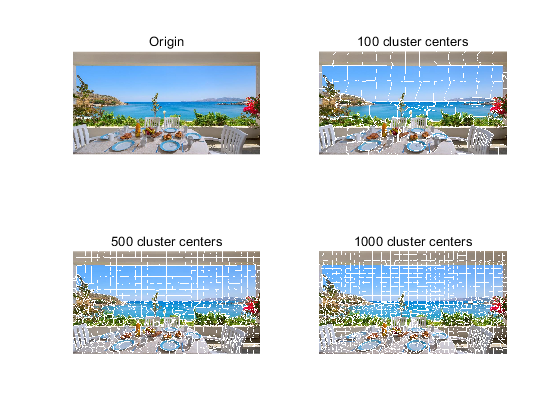

subplot(2,2,1);
imshow(sea_house);title('Origin');

% SLIC
corr = 30;
labels_100 = my_SLIC(100, corr, double(sea_house));
labels_500 = my_SLIC(500, corr, double(sea_house));
labels_1000 = my_SLIC(1000, corr, double(sea_house));

% set the color of boundary
sea_house_100 = Set_Color(sea_house, labels_100);
sea_house_500 = Set_Color(sea_house, labels_500);
sea_house_1000 = Set_Color(sea_house, labels_1000);

subplot(2,2,2);
imshow(sea_house_100);title('100 cluster centers');
subplot(2,2,3);
imshow(sea_house_500);title('500 cluster centers');
subplot(2,2,4);
imshow(sea_house_1000);title('1000 cluster centers');

function labels = my_SLIC(num_cluster, corr, image)
    [M,N,~] = size(image);
    R = double(image(:,:,1));
    G = double(image(:,:,2));
    B = double(image(:,:,3));

    step = floor(sqrt(M*N/num_cluster)+0.5);    
    % Initial the cluster center
    [cluster,num_cluster] = Initial_Cluster(step, M, N, R, G, B);
    % get super pixels
    [~,labels] = Get_Super_Pixel(cluster, num_cluster, M, N, step, corr, R, G, B);
    % connect
    k = floor(M*N/(step*step));
    labels = Connect(labels, M, N, k);
end

function [cluster, num_cluster] = Initial_Cluster(step, M, N, R, G, B)
    cluster = zeros(1,5); % [r, g, b, x, y]

    xsteps = floor(M/step);
    ysteps = floor(N/step);
    xerr = floor(M-step*xsteps);
    if xerr < 0 % error of x
        xsteps = xsteps-1;
        xerr = floor(M-step*xsteps);
    end
    
    yerr = floor(N-step*ysteps);
    if yerr < 0 % error of y
        ysteps = ysteps-1;
        yerr = floor(N-step*ysteps);
    end    
    
    n = 1;
    xoff = floor(step/2);
    yoff = floor(step/2);
    num_cluster = xsteps*ysteps;
    for x = 0:xsteps-1
        tmp_x = floor(x*xerr/xsteps);
        for y = 0:ysteps-1
            tmp_y = floor(y*yerr/ysteps);

            seedy = floor(y*step+yoff+tmp_y);
            seedx = floor(x*step+xoff+tmp_x);

            cluster(n,1) = R(seedx,seedy);
            cluster(n,2) = G(seedx,seedy);
            cluster(n,3) = B(seedx,seedy);
            cluster(n,4) = seedx;
            cluster(n,5) = seedy;
            n = n+1;
        end
    end
end

function [cluster, labels] = Get_Super_Pixel(cluster, num_cluster, M, N, step, corr, R, G, B)
    d = Inf(M,N); % set initial distance to +infinite
    labels = -1*ones(M,N); % set initial label to -1

    % calculate center cluster
    offset = step;
    for k = 1:10
        for i = 1:num_cluster
            % min x
            x_min = cluster(i,4)-offset;
            if x_min < 1
                x_min = 1;
            end

            % max x
            x_max = cluster(i,4)+offset;
            if x_max > M
                x_max = M;
            end

            % min y
            y_min = cluster(i,5)-offset;
            if y_min < 1
                y_min = 1;
            end

            % max y
            y_max = cluster(i,5)+offset;
            if y_max > N
                y_max = N;
            end   

            % get the distance
            for x = x_min:x_max
                for y = y_min:y_max
                    d_color = (cluster(i,1)-R(x,y))^2+(cluster(i,2)-G(x,y))^2+(cluster(i,3)-B(x,y))^2;
                    d_space = (cluster(i,4)-x)^2+(cluster(i,5)-y)^2;
                    D = d_color+d_space*(1/(step/corr)^2);

                    if D < d(x,y)
                        d(x,y) = D;
                        labels(x,y) = i;
                    end
                end
            end
        end
    end
    
    % get the clusters
    new_cluster = zeros(num_cluster,6); % [R, G, B, x, y, size]
    for x = 1:M
        for y = 1:N
            label = labels(x,y);
            
            new_cluster(label,1) = new_cluster(label,1)+R(x,y);
            new_cluster(label,2) = new_cluster(label,2)+G(x,y);
            new_cluster(label,3) = new_cluster(label,3)+B(x,y);
            new_cluster(label,4) = new_cluster(label,4)+x;    
            new_cluster(label,5) = new_cluster(label,5)+y;
            new_cluster(label,6) = new_cluster(label,6)+1;
        end
    end

    for i = 1:num_cluster
        cluster(i,:) = new_cluster(i,1:5)/new_cluster(i,6);
    end
end

function labels = Connect(labels, M, N, k)
    nlabels = -1*ones(M,N);
    label = 1;
    adj_label = 1;
    for x = 1:M
        for y = 1:N
            if nlabels(x,y) < 0
                nlabels(x,y) = label;
                if x-1 >= 1 && nlabels(x-1,y) >= 1
                    adj_label = nlabels(x-1,y);
                elseif x+1 <= M && nlabels(x+1,y) >= 1
                    adj_label = nlabels(x+1,y);
                elseif y-1 >= 1 && nlabels(x,y-1) >= 1
                    adj_label = nlabels(x,y-1);
                elseif y+1 <= N && nlabels(x,y+1) >= 1
                    adj_label = nlabels(x,y+1);
                end

                % find 4-adj points
                count = 1;
                points = [x,y];
                push_back = [x,y];
                while ~isempty(points)
                    p = points(1,:);
                    % up
                    if p(1)-1 >= 1
                        if nlabels(p(1)-1,p(2)) < 0 && labels(p(1)-1,p(2)) == labels(x,y)
                            points = cat(1,points,[p(1)-1,p(2)]);
                            push_back = cat(1,push_back,[p(1)-1,p(2)]);
                            nlabels(p(1)-1,p(2)) = label;
                            count = count+1;
                        end
                    end

                    % down
                    if p(1)+1 <= M
                        if nlabels(p(1)+1,p(2)) < 0 && labels(p(1)+1,p(2)) == labels(x,y)
                            points = cat(1,points,[p(1)+1,p(2)]);
                            push_back = cat(1,push_back,[p(1)+1,p(2)]);
                            nlabels(p(1)+1,p(2)) = label;
                            count = count+1;
                        end
                    end

                    % left
                    if p(2)-1 >= 1
                        if nlabels(p(1),p(2)-1) < 0 && labels(p(1),p(2)-1) == labels(x,y)
                            points = cat(1,points,[p(1),p(2)-1]);
                            push_back = cat(1,push_back,[p(1),p(2)-1]);
                            nlabels(p(1),p(2)-1) = label;
                            count = count+1;
                        end
                    end

                    % right
                    if p(2)+1 <= N
                        if nlabels(p(1),p(2)+1) < 0 && labels(p(1),p(2)+1) == labels(x,y)
                            points = cat(1,points,[p(1),p(2)+1]);
                            push_back = cat(1,push_back,[p(1),p(2)+1]);
                            nlabels(p(1),p(2)+1) = label;
                            count = count+1;
                        end
                    end  
                    points(1,:) = [];
                end

                % until E<= threshold
                if count <= floor(M*N/k)/4
                    while ~isempty(push_back)
                        p = push_back(1,:);
                        nlabels(p(1),p(2)) = adj_label;
                        push_back(1,:) = [];
                    end
                    label = label-1;
                end
                label = label+1;
            end
        end
    end
    labels = nlabels;
end

function output = Set_Color(image, labels)
    [m,n] = size(labels);
    output = image;
    for i = 1:m
        for j = 1:n
            top = labels(max(1,i-1),j);
            bottom = labels(min(m,i+1),j);
            left = labels(i,max(1,j-1));
            right = labels(i,min(n,j+1));
            if ~(top == bottom && bottom == left && left == right)
                output(i,j,:) = 255;
            end
        end
    end
end